# Load file

clear all;

% path = '/Users/ssense/Desktop/MEA-analysis/Data/PV-ArchT/rawData/';
% recording = 'PAT200219_2C_DIV170002.mat';

path = '/Users/jeremi/mea/Data/';
recording = '200114_FTDOrg_GrpD_5A_Slice12.mat';

fileName = [path recording];
file = load(fileName);
data = file.dat;
channels = file.channels;
fs = file.fs;

## Parameters

channel = 41;
trace = data(:, channel);
trace = trace(1:25000*120);

Wid = [0.5 1.0];
wname_list = {'bior1.5','bior1.3','mea','db2'};
% wname_list = {'mea'};
L = -0.3;
Ns = 5;
multiplier = 2.5;
n_spikes = 200;
ttx = contains(fileName, 'TTX');

## Detect spikes

spike_struct = struct;

for wname = wname_list
    sFr = [];
    wname = char(wname);
    
    [spikeFrames, ~, filtTrace, threshold] = detectFramesCWT(trace, fs, Wid, wname, L, Ns, multiplier, ...
        n_spikes, ttx);
    
    valid_wname = strrep(wname, '.', 'p');
    spike_struct.(valid_wname) = spikeFrames;
end

## Save spike structure

savePath = '/Users/jeremi/mea/CWT/';
newFile = [recording(1:end-4) '_L=' num2str(L) '_spike_struct' '.mat'];
    newFileName = [savePath newFile];
save(newFileName, 'spike_struct');

## Load spike structure and merge spikes

load(newFileName);
wavelets = fieldnames(spike_struct);

%   Merge all spikes together
all_spikes = [];
for wav = 1:numel(wavelets)
    all_spikes = union(all_spikes, spike_struct.(wavelets{wav}));
end
% all_spikes = unique(all_spikes);

## Generate intersection matrix

clear F;
intersectMatrix = zeros(length(all_spikes),length(wavelets));

for wav = 1:length(wavelets)
    spikeTimes = spike_struct.(wavelets{wav});
    for spikeIndex = 1:length(all_spikes)
        if ismember(all_spikes(spikeIndex), spikeTimes)
            intersectMatrix(spikeIndex, wav) = 1;
        end
    end
end

for spike = 1:length(intersectMatrix)
    clear ff
    ff = find(intersectMatrix(spike, :) == 1);
    if length(ff) == 1 && ff ~=0
        F(spike) = ff;
    end
end

## Plot raw trace with spike markers

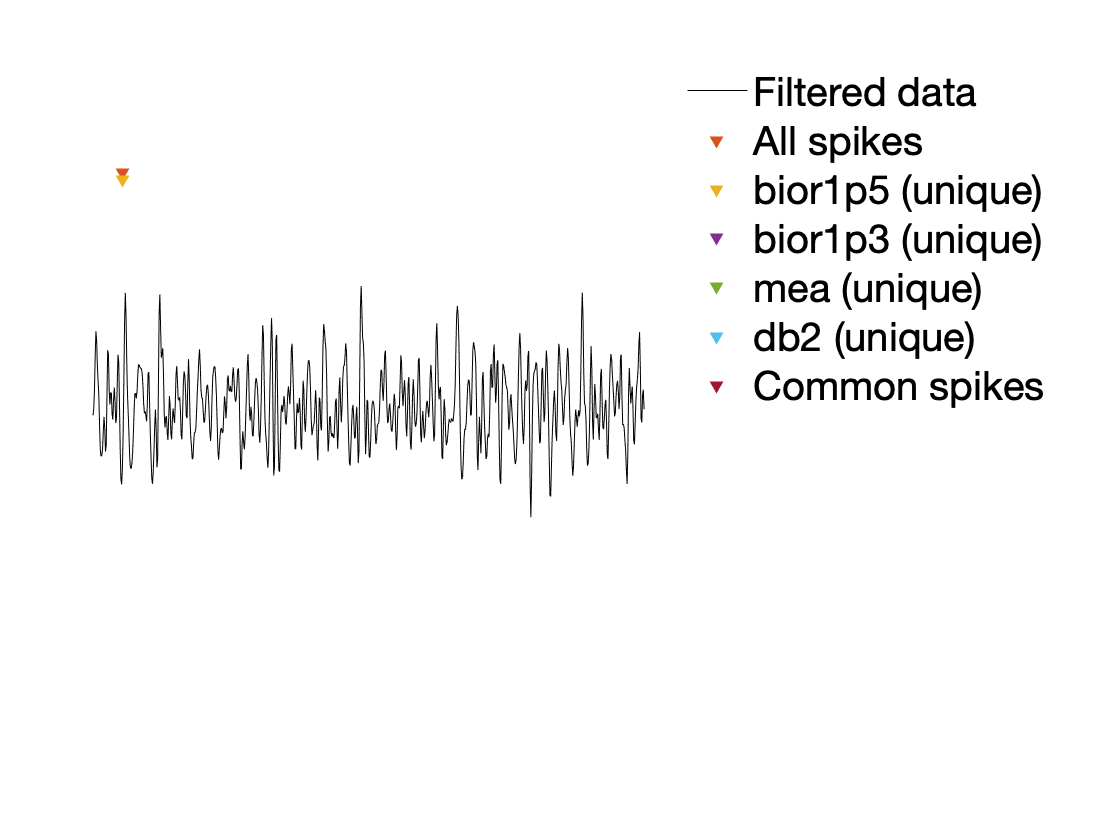

close all;

%   Plot raw trace
figure()
plot(filtTrace,'k');
hold on;
yOffset = max(filtTrace+5);

%   Plot all spikes

y = repmat(yOffset - 0, ...
    length(all_spikes), 1);
   
spikeCounts{1} = length(y);

scatter((all_spikes)', ...
    y(:,1), 'v','filled');
hold on;

%   Plot unique spikes for each wavelet
for wav = 1:length(wavelets)
    
    uqSpkIdx = find(F == wav);
    uniqueSpikes = all_spikes(uqSpkIdx);
    
    y = repmat(yOffset - wav, ...
        length(uniqueSpikes), 1);
    spikeCounts{wav+1} = length(y);
    
    scatter((uniqueSpikes)', ...
        y(:,1), 'v','filled');
    hold on;
end

%   Plot common spikes (detected by all the wavelets)
uqSpkIdx = find(F == 0);
uniqueSpikes = all_spikes(uqSpkIdx);

y = repmat(yOffset - 5, ...
    length(uniqueSpikes), 1);
spikeCounts{6} = length(y);

scatter((uniqueSpikes)', ...
    y(:,1), 'v','filled');
hold on;

%   Add labels, etc.
legend_labels = [{'Filtered data' ;['All spikes']}; strcat(wavelets, ' (unique)');'Common spikes'];
l = legend(legend_labels);
l.Location = 'northeastoutside';
l.FontSize = 20;
l.Box = 'off';
title({['Total no. of spikes = ' num2str(length(all_spikes))],['Concordance between wavelets = ' num2str(100*1414/length(all_spikes)) '%'],['L = ', num2str(L)],['']},'FontSize',20);
set(gca, 'Visible', 'off')

%   Plot time B with most spikes
ms = 30;
t = 1:(ms*fs/1000):length(filtTrace);
spikeVector = zeros(size(filtTrace));

wavelet = 1;
% spikeVector(all_spikes(find(intersectMatrix(:, wavelet) == 1))) = 1;
spikeVector(all_spikes(find(F == wavelet))) = 1;


for B = 1:length(t)-1
    BCount(B) = sum(spikeVector(t(B):t(B+1)));
end
BMax = find(BCount == max(BCount));
BMax = BMax(1);

xlim([t(BMax) t(BMax+1)])
ylim([-yOffset-15 yOffset+15])

%     set(gca,'ColorOrder', cool(10));

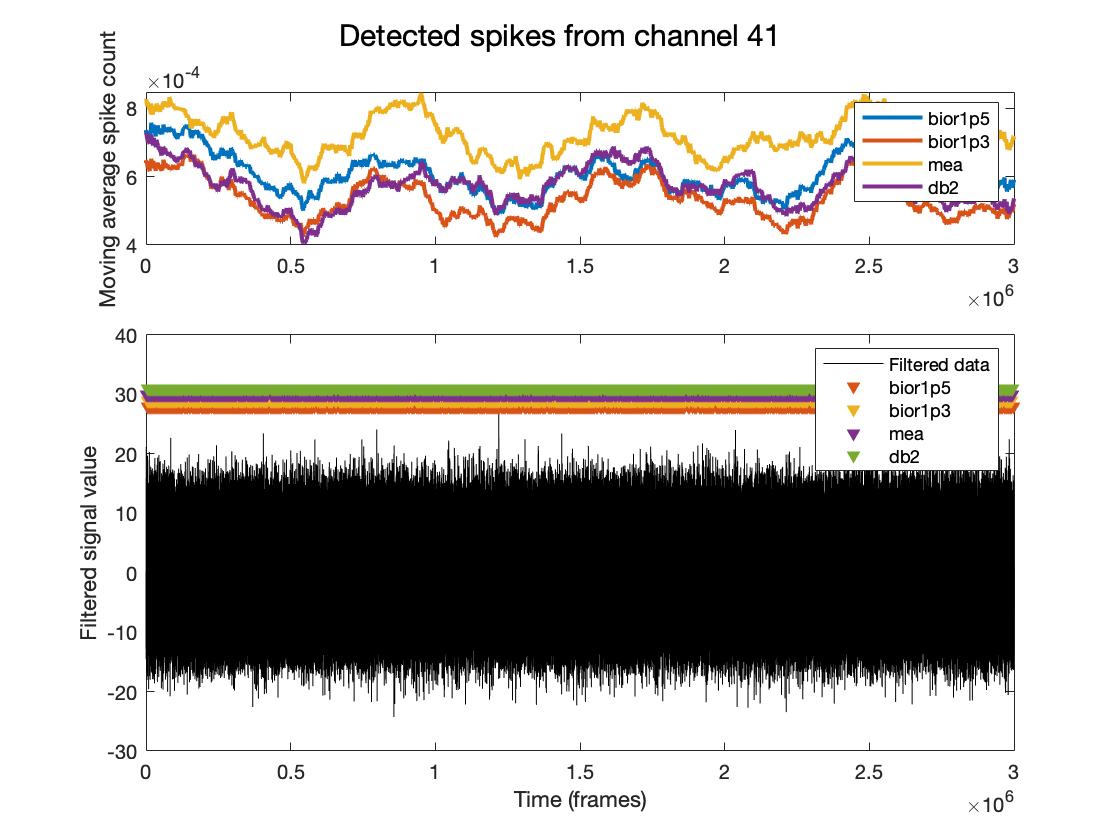

close all;
moving_average_dur_in_sec = 10;
moving_average_window_frame = moving_average_dur_in_sec * fs;

figure()
ax1 = subplot(3, 1, 1);
caxis([1 4])
for wav = 1:numel(wavelets)
    spike_train = zeros(length(filtTrace), 1);
    spike_train(spike_struct.(wavelets{wav})) = 1;
    spike_count_moving_mean = movmean(spike_train, moving_average_window_frame);
    plot(spike_count_moving_mean, 'Linewidth', 2)
%     set(gca,'ColorOrder',bone(wav+2));
    hold on;
end

legend(wavelets)

ylabel('Moving average spike count')

ax2 = subplot(3, 1, [2, 3]);
% plot the filtered trace
plot(filtTrace,'k')
hold on;

yOffset = max(filtTrace);
for wav = 1:numel(wavelets)
    scatter(spike_struct.(wavelets{wav}), ...
        repmat(yOffset + wav, ...
        length(spike_struct.(wavelets{wav})), 1), 'v','filled');
%     set(gca,'ColorOrder',bone(wav+3));
    hold on;
end

legend_labels = [{'Filtered data'}; wavelets];
legend(legend_labels);
ylabel('Filtered signal value')
xlabel('Time (frames)')
caxis([1 4])

linkaxes([ax1, ax2], 'x');

% TODO: generalise this
sgtitle(['Detected spikes from channel ', num2str(channel)]);

## Spikes heatmap

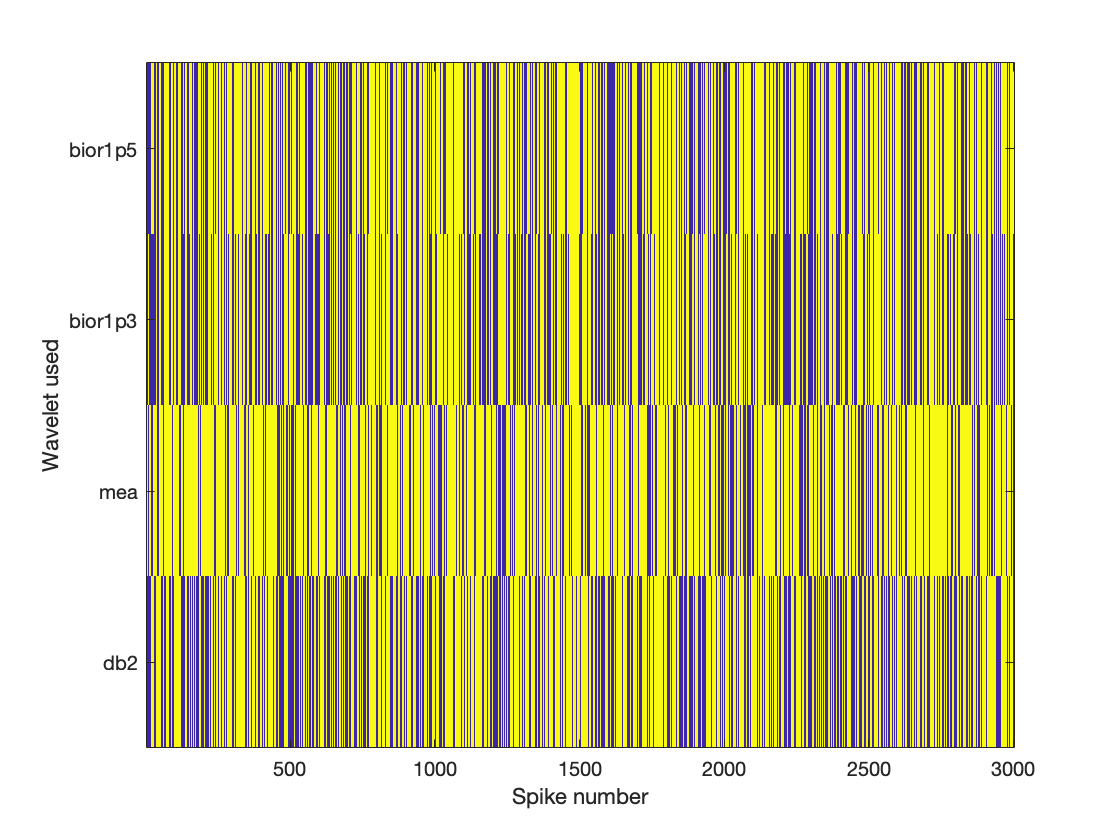

figure()
imagesc(intersectMatrix')
xlabel('Spike number')
yticks(1:length(wavelets));
yticklabels(wavelets)
ylabel('Wavelet used')

## Plot spikes that are shared by all wavelets

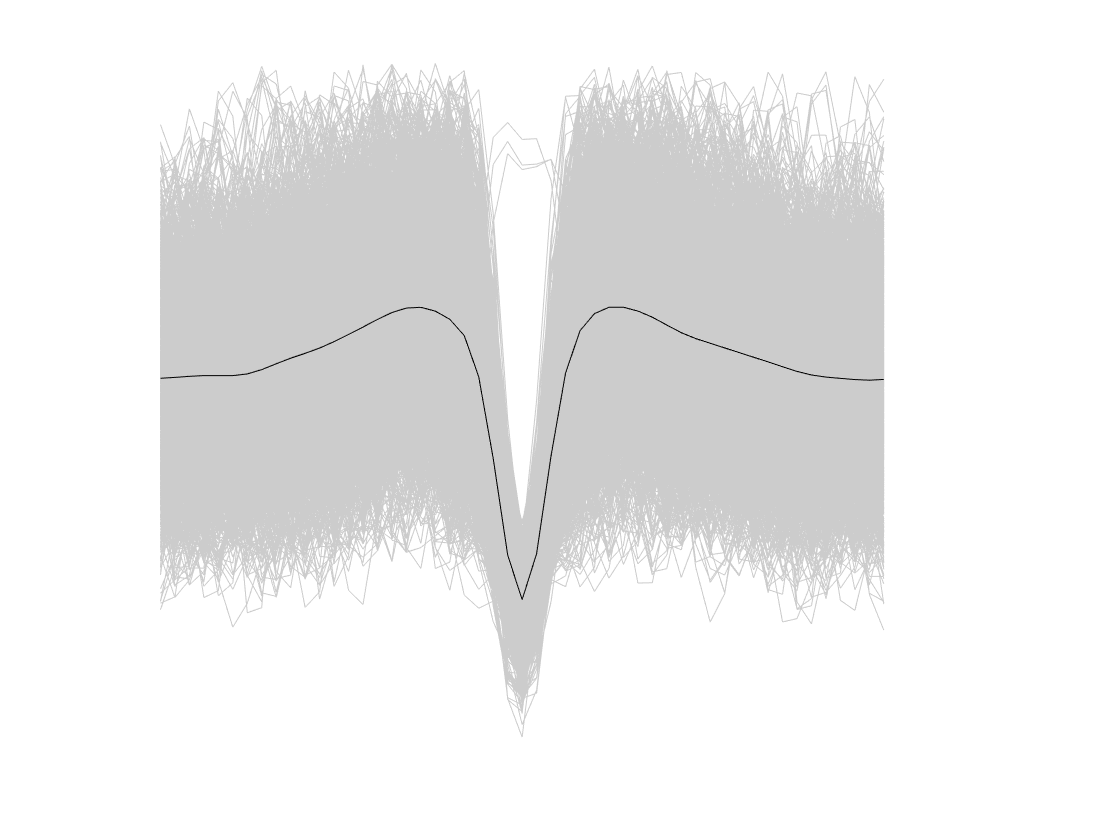

close all;
spTrain = zeros(length(data),1);
spTrain(all_spikes) = 1;
alignment_duration = 0.01;
[spikeWaves, averageSpike] = spikeAlignment(filtTrace, spTrain, ...
    fs, alignment_duration);
peak_alignment_duration = 0.002;
spike_aligment_method = 'peakghost';
figure()
plotSpikeAlignment(spikeWaves, spike_aligment_method, ...
    fs, peak_alignment_duration)
xlabel('Time Bs')
ylabel('Filtered amplitude')
title('Waveform of spikes detected by all wavelets')
set(gca, 'Visible', 'off');
xlabel('Time Bs')
ylabel('Filtered amplitude')
title('Waveform of spikes detected by all wavelets')

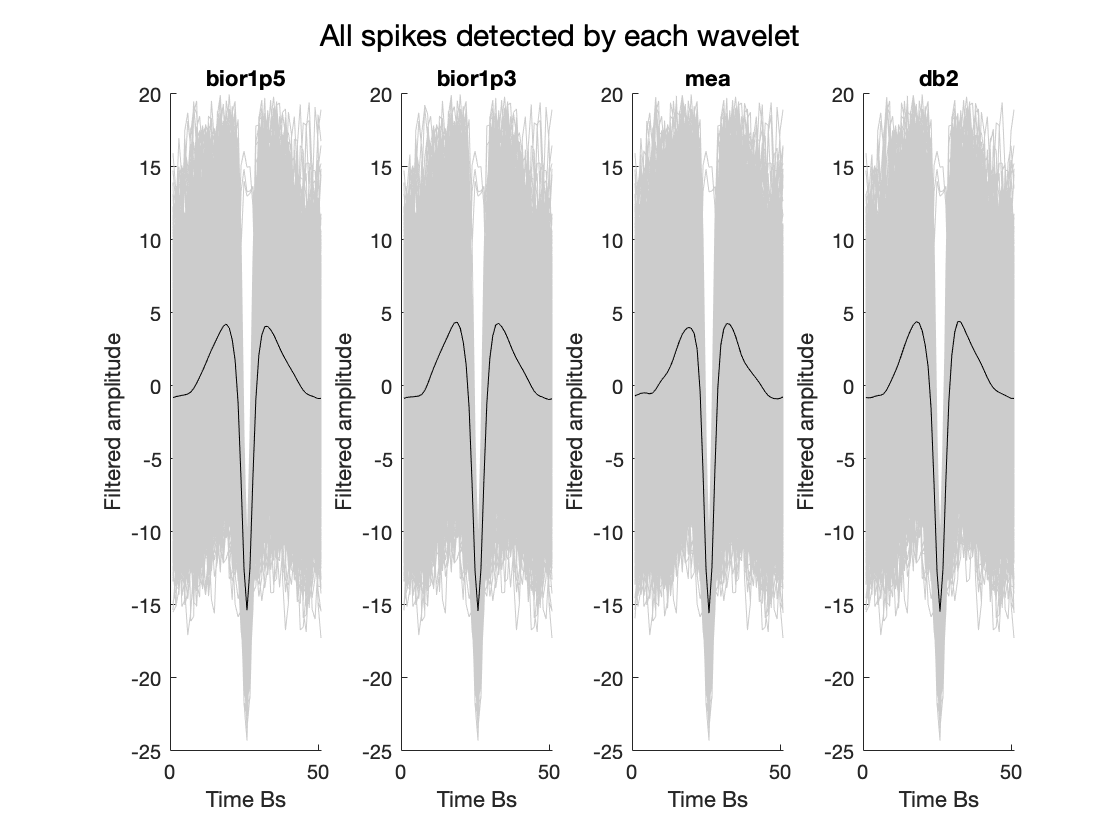


figure()
for wav = 1:numel(wavelets)
    subplot(1, numel(wavelets), wav)
    
    spike_idx_given_wavelet = find((intersectMatrix(:, wav) == 1));
    spike_times_given_wavelet = all_spikes(spike_idx_given_wavelet);
    spTrain = zeros(length(spike_times_given_wavelet),1);
    spTrain(spike_times_given_wavelet) = 1;
    
    grossTotal.(wavelets{wav}) = length(spike_times_given_wavelet);
    
    if length(spike_times_given_wavelet) >= 3
        
        [spikeWaves, averageSpike] = spikeAlignment(filtTrace, spTrain, ...
            fs, alignment_duration);
        plotSpikeAlignment(spikeWaves, spike_aligment_method, ...
            fs, peak_alignment_duration)
        box off;
        xlabel('Time Bs')
        ylabel('Filtered amplitude')
        
        title(wavelets{wav});
    end
    
end
sgtitle('All spikes detected by each wavelet')

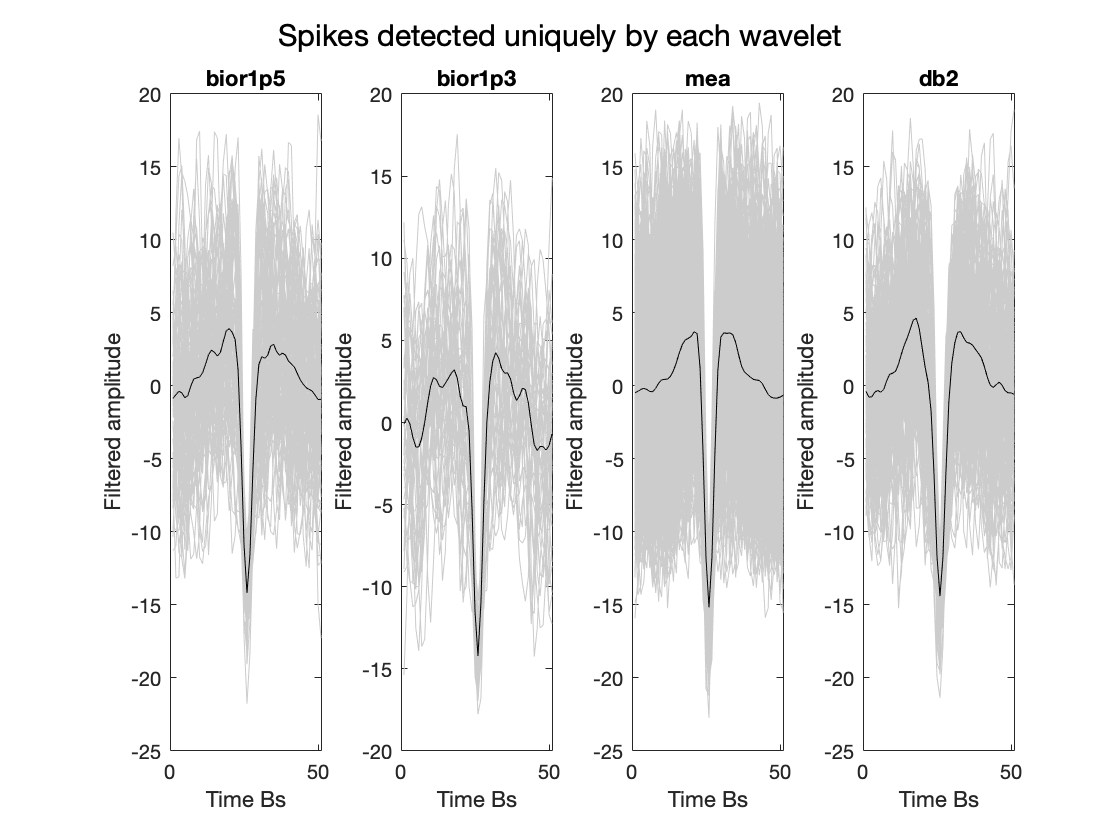

figure()
uniqueTotal = struct;
for wav = 1:numel(wavelets)
    subplot(1, numel(wavelets), wav)
    
    spike_idx_unique_to_wavelet = find(...
        (sum(intersectMatrix, 2) == 1) & ...
        (intersectMatrix(:, wav) == 1) ...
        );
    
    uniqueTotal.(wavelets{wav}) = length(spike_idx_unique_to_wavelet);
    spike_times_unique_to_wavelet = all_spikes(spike_idx_unique_to_wavelet);
    spTrain = zeros(length(spike_times_unique_to_wavelet),1);
    spTrain(spike_times_unique_to_wavelet) = 1;
    
    if length(spike_times_unique_to_wavelet) >= 3
        
        [spikeWaves, averageSpike] = spikeAlignment(filtTrace, spTrain, ...
            fs, alignment_duration);
        plotSpikeAlignment(spikeWaves, spike_aligment_method, ...
            fs, peak_alignment_duration)
        xlabel('Time Bs')
        ylabel('Filtered amplitude')
%         aesthetics
        
        title(wavelets{wav});
    end
    
end
sgtitle('Spikes detected uniquely by each wavelet')

for wname = wname_list
    wname = char(wname);
    valid_wname = strrep(wname, '.', 'p');
    disp(['No of unique spikes ', wname,' = ', num2str(uniqueTotal.(valid_wname))])
    disp(['No of all spikes ', wname,' = ', num2str(grossTotal.(valid_wname))])
end

No of unique spikes bior1.5 = 97


No of all spikes bior1.5 = 1809


No of unique spikes bior1.3 = 47


No of all spikes bior1.3 = 1610


No of unique spikes mea = 764


No of all spikes mea = 2161


No of unique spikes db2 = 165


No of all spikes db2 = 1718


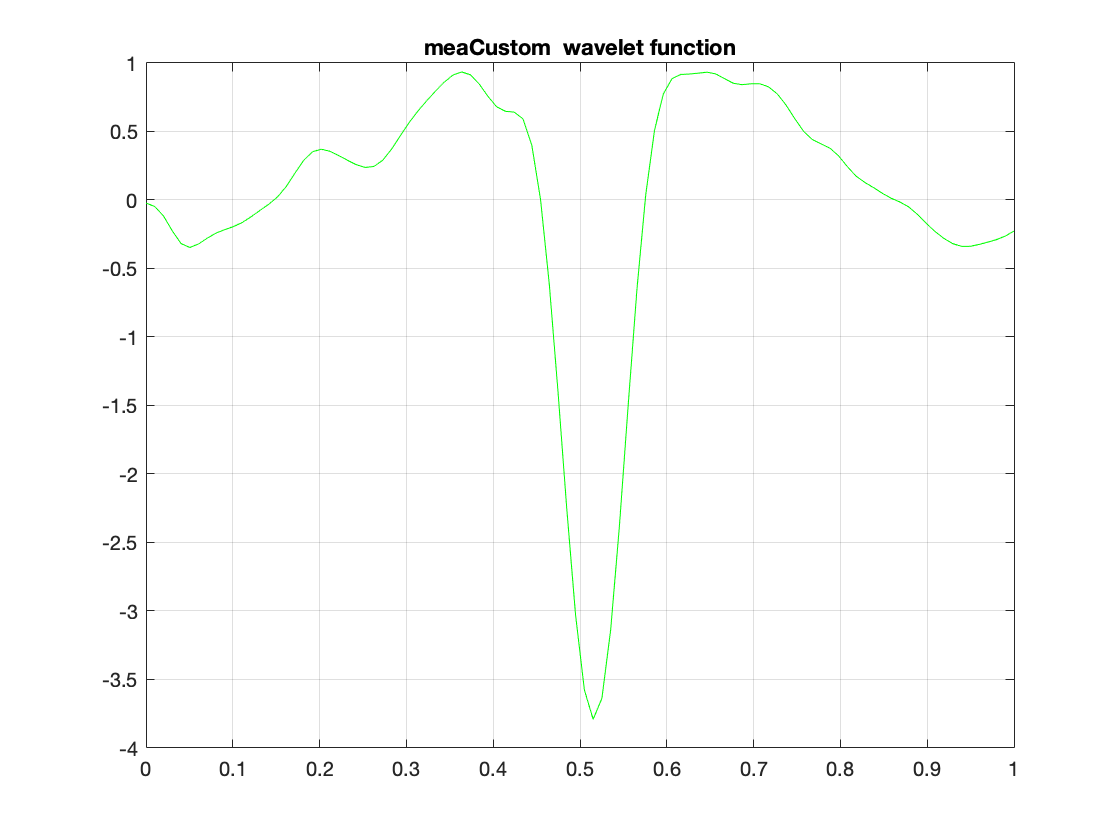

close all;
wavefun('mea', 0);